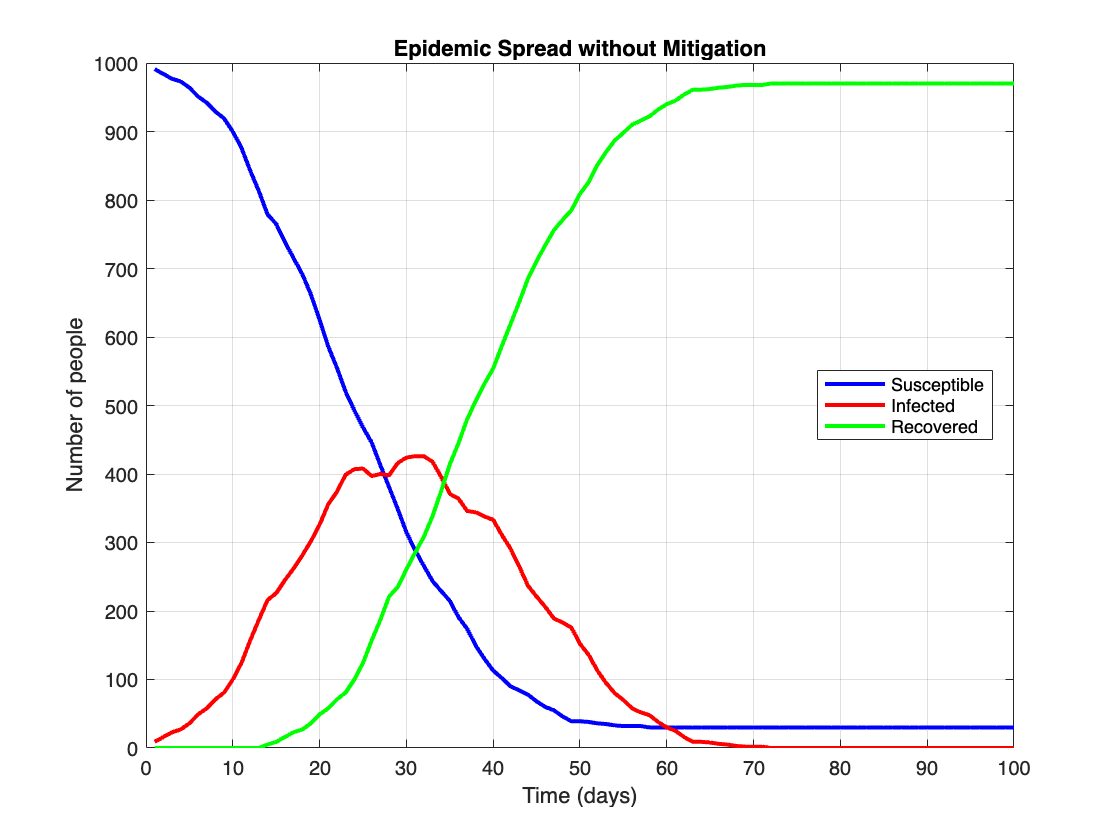

% Epidemic Modeling and Mitigation Strategies
% Agent-Based Model for Disease Spread Simulation

% Model Parameters
num_agents = 1000;
initial_infected = 5;
simulation_days = 100;
world_size = 100;
infection_radius = 2;
infection_probability = 0.3;
recovery_time = 14;

% Function to run a single simulation
function [S, I, R, V] = run_simulation(params)
    % Initialize Agents
    agents = struct('x', num2cell(rand(1, params.num_agents) * params.world_size), ...
                    'y', num2cell(rand(1, params.num_agents) * params.world_size), ...
                    'status', repmat({'S'}, 1, params.num_agents), ...
                    'days_infected', num2cell(zeros(1, params.num_agents)), ...
                    'vaccinated', num2cell(false(1, params.num_agents)));

    % Randomly infecting initial agents
    infected_indices = randperm(params.num_agents, params.initial_infected);
    [agents(infected_indices).status] = deal('I');

    % Data Storage Initialization
    S = zeros(1, params.simulation_days);
    I = zeros(1, params.simulation_days);
    R = zeros(1, params.simulation_days);
    V = zeros(1, params.simulation_days);

    % Main Simulation Loop
    for day = 1:params.simulation_days
        % Updating agent statuses and positions
        for i = 1:params.num_agents
            % Moving agent randomly
            move_distance = 2 - params.social_distance;
            agents(i).x = mod(agents(i).x + randn() * move_distance, params.world_size);
            agents(i).y = mod(agents(i).y + randn() * move_distance, params.world_size);
            
            % Applying vaccination
            if strcmp(agents(i).status, 'S') && ~agents(i).vaccinated && rand() < params.vaccination_rate
                agents(i).vaccinated = true;
            end
            
            % Updating infected agents
            if strcmp(agents(i).status, 'I')
                agents(i).days_infected = agents(i).days_infected + 1;
                if agents(i).days_infected >= params.recovery_time
                    agents(i).status = 'R';
                end
            end
        end
        
        % Checking for new infections
        for i = 1:params.num_agents
            if strcmp(agents(i).status, 'S')
                for j = 1:params.num_agents
                    if strcmp(agents(j).status, 'I')
                        distance = sqrt((agents(i).x - agents(j).x)^2 + (agents(i).y - agents(j).y)^2);
                        if distance <= params.infection_radius
                            effective_probability = params.infection_probability * (1 - 0.7 * agents(i).vaccinated);
                            if rand() < effective_probability
                                agents(i).status = 'I';
                                break;
                            end
                        end
                    end
                end
            end
        end
        
        % Counting current status
        S(day) = sum(strcmp({agents.status}, 'S'));
        I(day) = sum(strcmp({agents.status}, 'I'));
        R(day) = sum(strcmp({agents.status}, 'R'));
        V(day) = sum([agents.vaccinated]);
    end
end

% Function to plot results
function plot_results(S, I, R, V, title_text)
    figure;
    plot(1:length(S), S, 'b-', 1:length(I), I, 'r-', 1:length(R), R, 'g-', 'LineWidth', 2);
    if ~isempty(V)
        hold on;
        plot(1:length(V), V, 'm--', 'LineWidth', 1.5);
        legend('Susceptible', 'Infected', 'Recovered', 'Vaccinated', 'Location', 'Best');
    else
        legend('Susceptible', 'Infected', 'Recovered', 'Location', 'Best');
    end
    xlabel('Time (days)');
    ylabel('Number of people');
    title(title_text);
    grid on;
end

% Base parameters
base_params = struct('num_agents', num_agents, 'initial_infected', initial_infected, ...
                     'simulation_days', simulation_days, 'world_size', world_size, ...
                     'infection_radius', infection_radius, 'infection_probability', infection_probability, ...
                     'recovery_time', recovery_time, 'vaccination_rate', 0, 'social_distance', 0);

% 1. No mitigation strategies
[S, I, R, ~] = run_simulation(base_params);
plot_results(S, I, R, [], 'Epidemic Spread without Mitigation');

fprintf('No Mitigation:\n');

No Mitigation:


fprintf('  Peak Infections: %d\n', max(I));

  Peak Infections: 426


fprintf('  Total Infections: %d\n\n', num_agents - S(end));

  Total Infections: 970



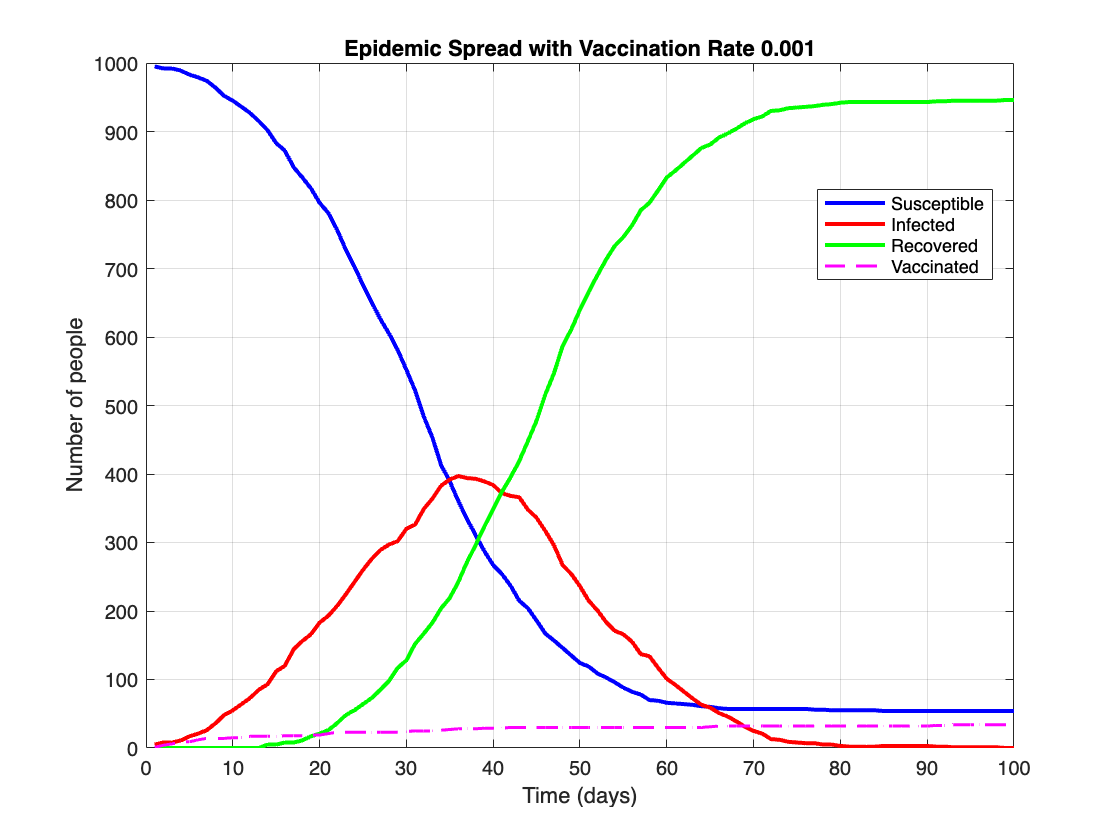

Vaccination Rate 0.001:


  Peak Infections: 397


  Total Infections: 912


  Final Vaccinated: 34



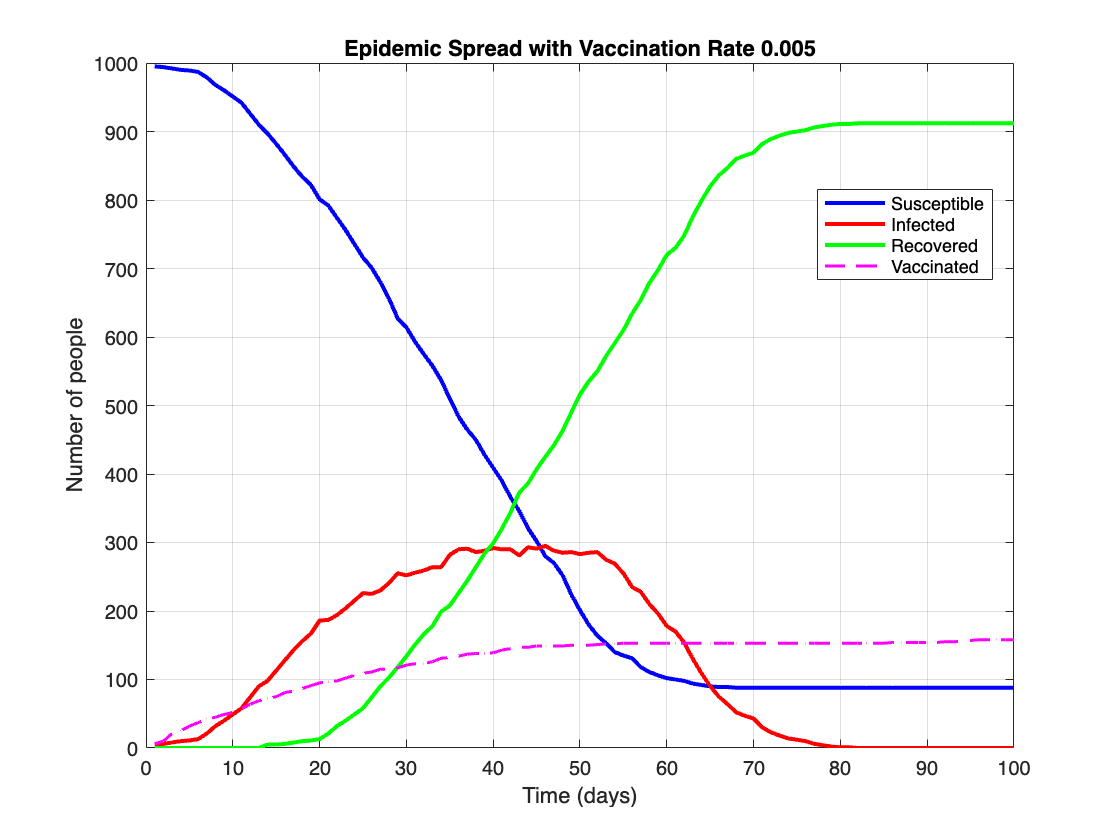

Vaccination Rate 0.005:


  Peak Infections: 295


  Total Infections: 754


  Final Vaccinated: 158



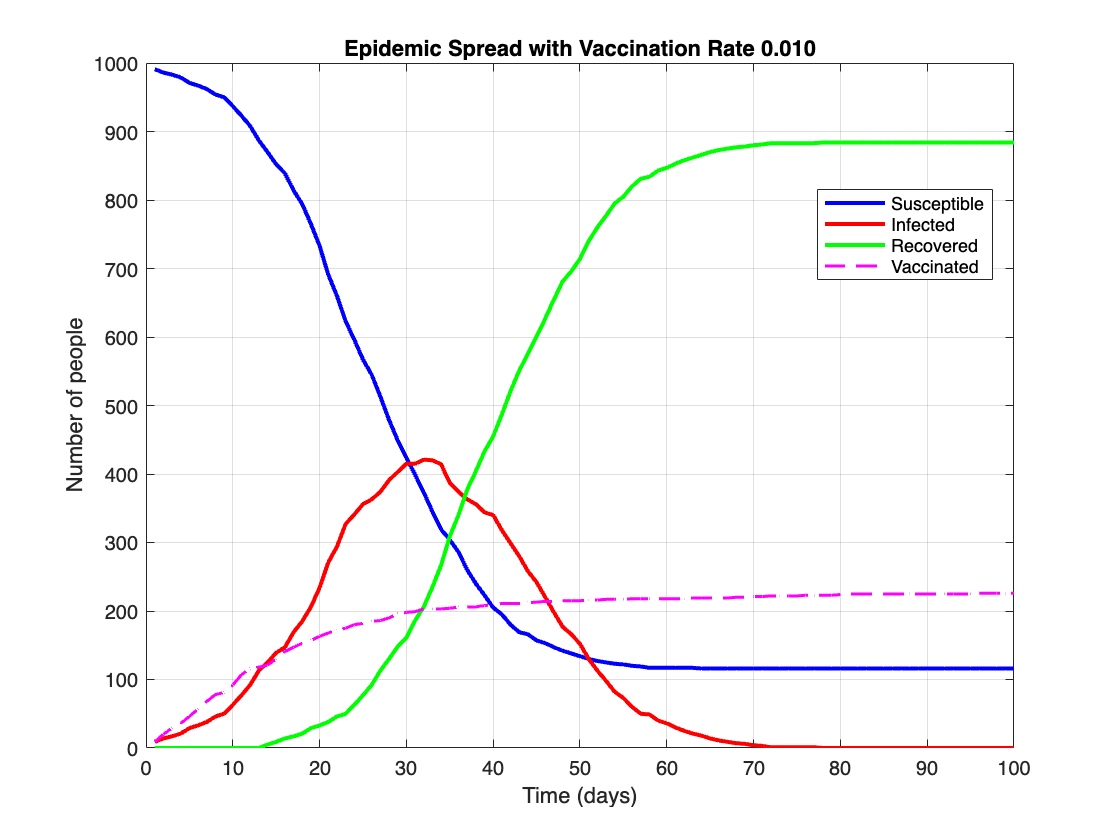

Vaccination Rate 0.010:


  Peak Infections: 421


  Total Infections: 658


  Final Vaccinated: 226




% 2. Vaccination strategies
vaccination_rates = [0.001, 0.005, 0.01];
for i = 1:length(vaccination_rates)
    params = base_params;
    params.vaccination_rate = vaccination_rates(i);
    [S, I, R, V] = run_simulation(params);
    plot_results(S, I, R, V, sprintf('Epidemic Spread with Vaccination Rate %.3f', vaccination_rates(i)));
    fprintf('Vaccination Rate %.3f:\n', vaccination_rates(i));
    fprintf('  Peak Infections: %d\n', max(I));
    fprintf('  Total Infections: %d\n', num_agents - S(end) - V(end));
    fprintf('  Final Vaccinated: %d\n\n', V(end));
end

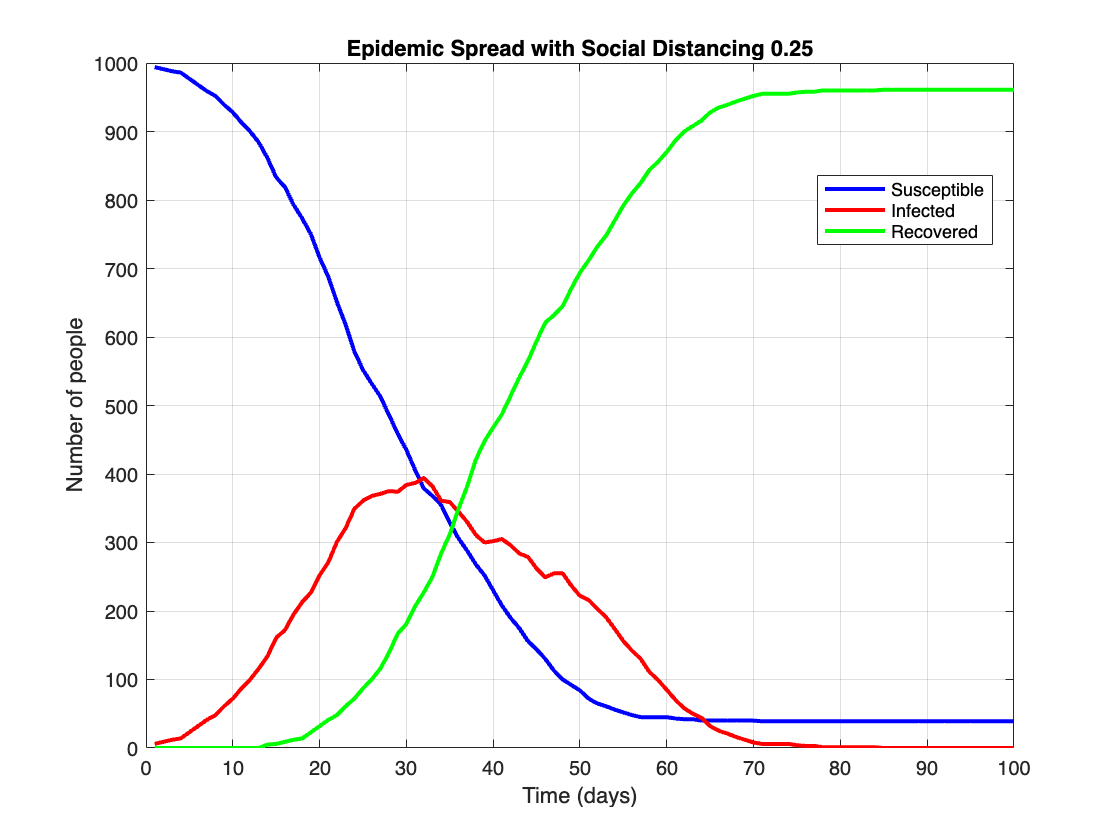

Social Distancing 0.25:


  Peak Infections: 394


  Total Infections: 961



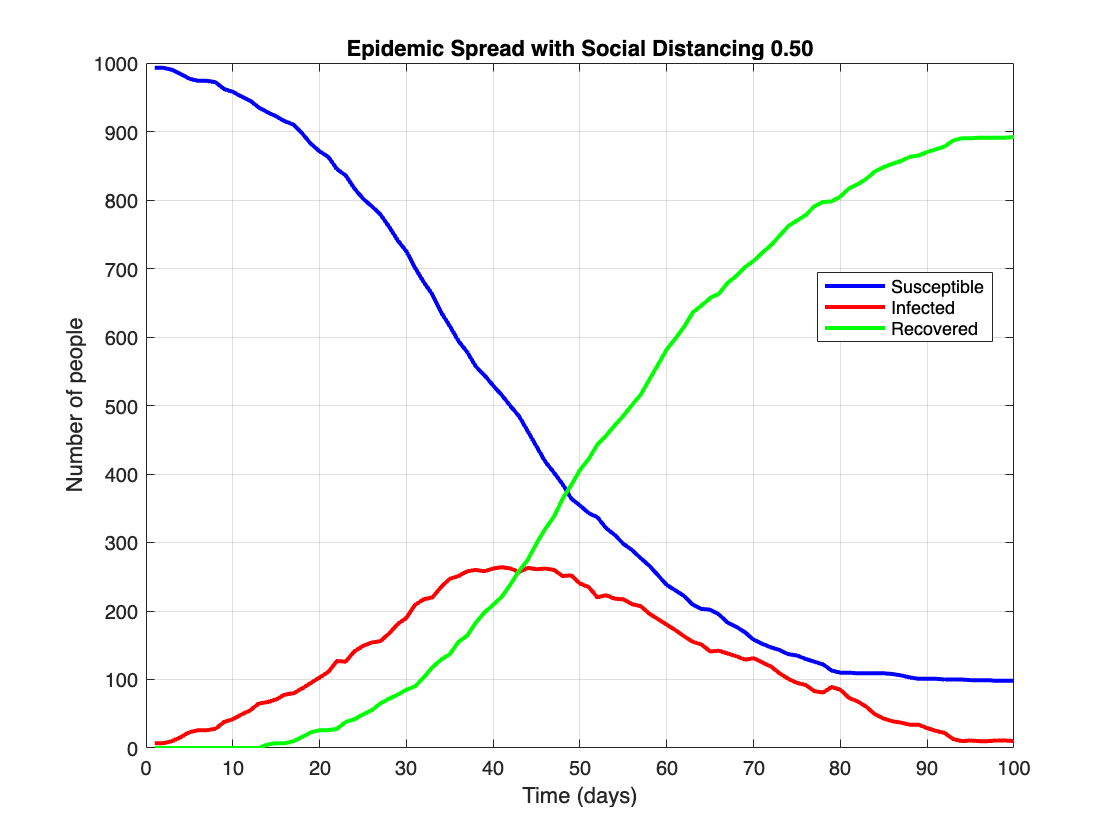

Social Distancing 0.50:


  Peak Infections: 264


  Total Infections: 902



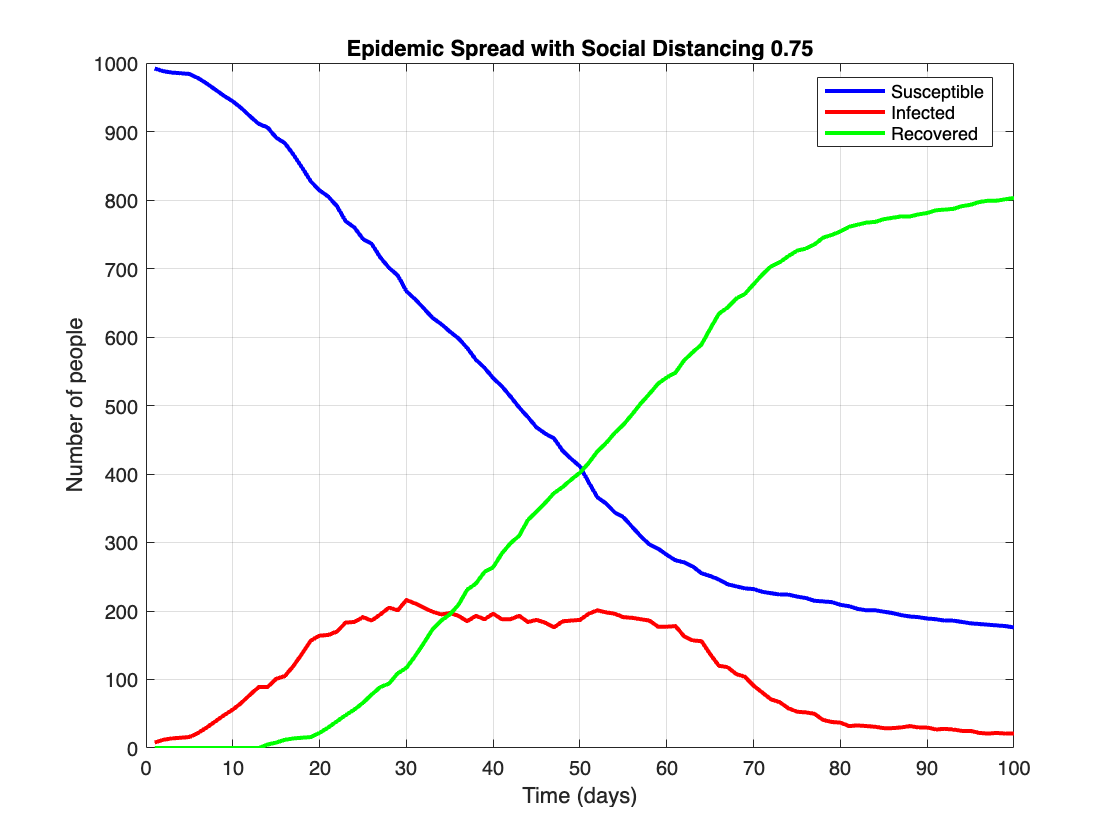

Social Distancing 0.75:


  Peak Infections: 216


  Total Infections: 824




% 3. Social distancing strategies
social_distancing_levels = [0.25, 0.5, 0.75];
for i = 1:length(social_distancing_levels)
    params = base_params;
    params.social_distance = social_distancing_levels(i);
    [S, I, R, ~] = run_simulation(params);
    plot_results(S, I, R, [], sprintf('Epidemic Spread with Social Distancing %.2f', social_distancing_levels(i)));
    fprintf('Social Distancing %.2f:\n', social_distancing_levels(i));
    fprintf('  Peak Infections: %d\n', max(I));
    fprintf('  Total Infections: %d\n\n', num_agents - S(end));
end

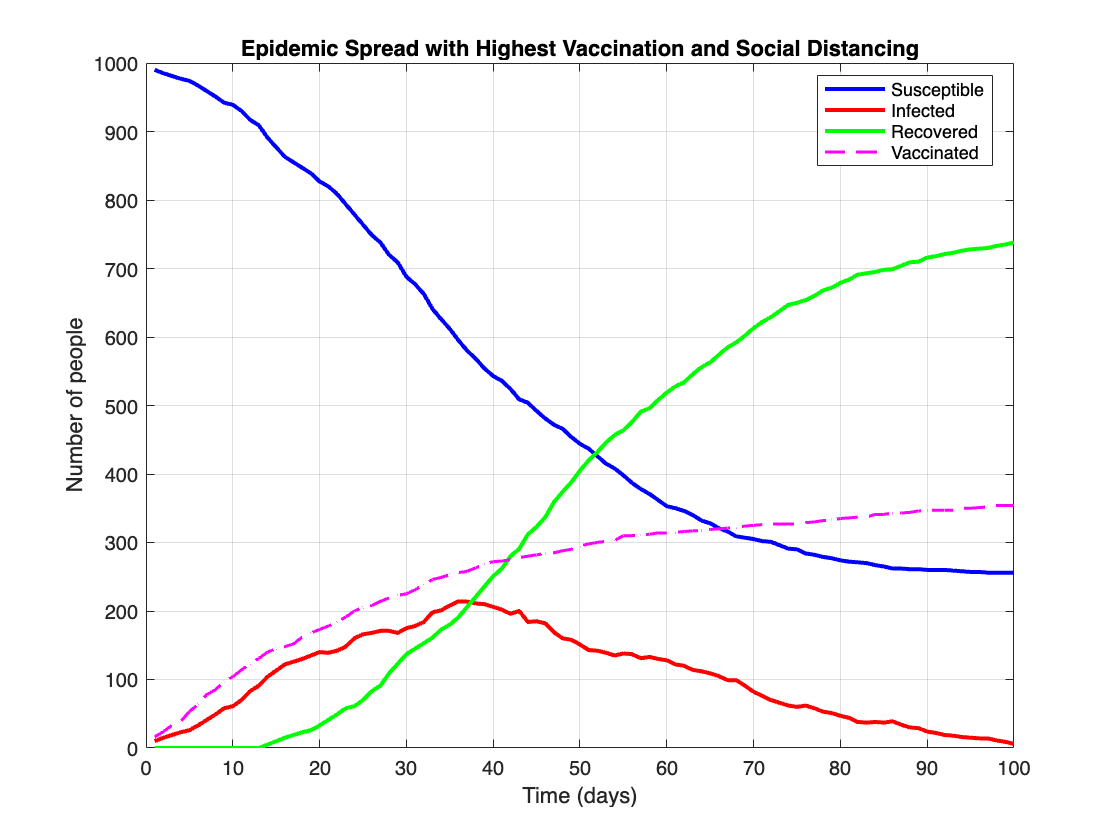


% 4. Highest vaccination rate and social distancing
params = base_params;
params.vaccination_rate = max(vaccination_rates);
params.social_distance = max(social_distancing_levels);
[S, I, R, V] = run_simulation(params);
plot_results(S, I, R, V, 'Epidemic Spread with Highest Vaccination and Social Distancing');

fprintf('Highest Vaccination (%.3f) and Social Distancing (%.2f):\n', params.vaccination_rate, params.social_distance);

Highest Vaccination (0.010) and Social Distancing (0.75):


fprintf('  Peak Infections: %d\n', max(I));

  Peak Infections: 214


fprintf('  Total Infections: %d\n', num_agents - S(end) - V(end));

  Total Infections: 390


fprintf('  Final Vaccinated: %d\n', V(end));

  Final Vaccinated: 354


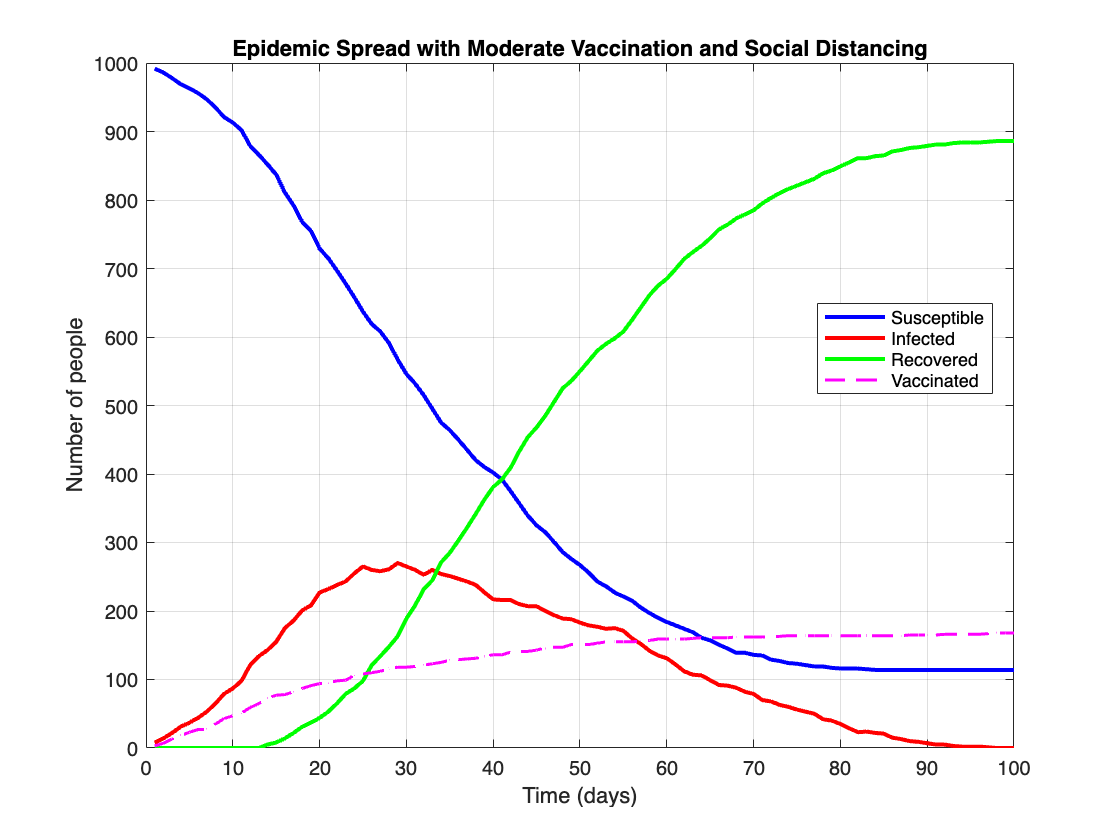


% 5. Combined moderate vaccination and social distancing
params = base_params;
params.vaccination_rate = vaccination_rates(2);  % Moderate vaccination rate
params.social_distance = social_distancing_levels(2);  % Moderate social distancing
[S, I, R, V] = run_simulation(params);
plot_results(S, I, R, V, 'Epidemic Spread with Moderate Vaccination and Social Distancing');

fprintf('Moderate Vaccination (%.3f) and Social Distancing (%.2f):\n', params.vaccination_rate, params.social_distance);

Moderate Vaccination (0.005) and Social Distancing (0.50):


fprintf('  Peak Infections: %d\n', max(I));

  Peak Infections: 270


fprintf('  Total Infections: %d\n', num_agents - S(end) - V(end));

  Total Infections: 718


fprintf('  Final Vaccinated: %d\n\n', V(end));

  Final Vaccinated: 168



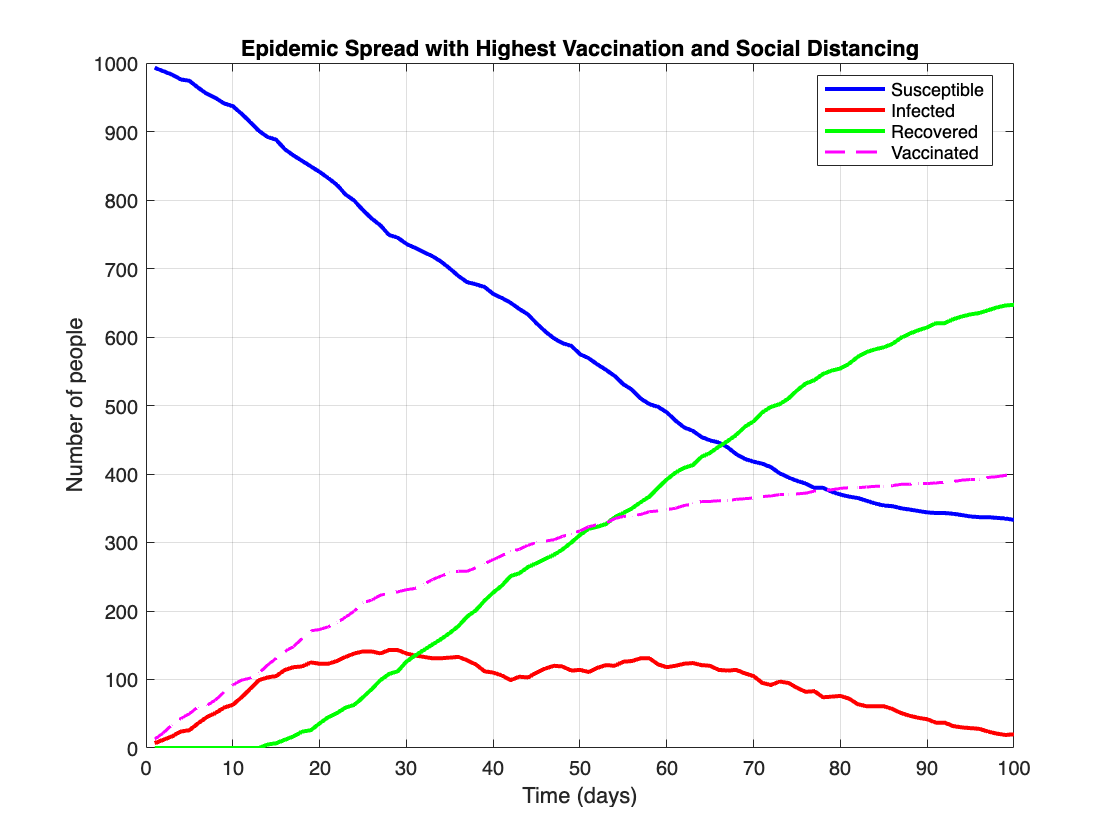


% 6. Combined highest vaccination and social distancing
params = base_params;
params.vaccination_rate = max(vaccination_rates);
params.social_distance = max(social_distancing_levels);
[S, I, R, V] = run_simulation(params);
plot_results(S, I, R, V, 'Epidemic Spread with Highest Vaccination and Social Distancing');

fprintf('Highest Vaccination (%.3f) and Social Distancing (%.2f):\n', params.vaccination_rate, params.social_distance);

Highest Vaccination (0.010) and Social Distancing (0.75):


fprintf('  Peak Infections: %d\n', max(I));

  Peak Infections: 143


fprintf('  Total Infections: %d\n', num_agents - S(end) - V(end));

  Total Infections: 268


fprintf('  Final Vaccinated: %d\n\n', V(end));

  Final Vaccinated: 399



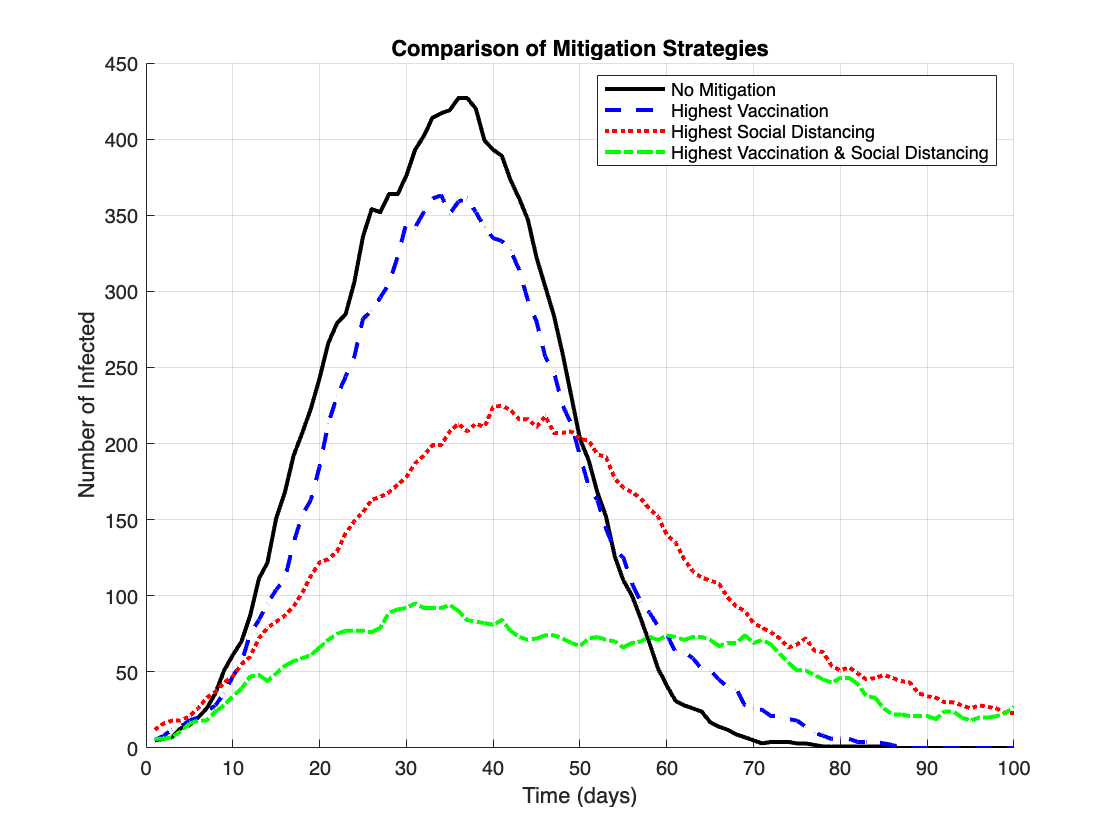


% 7. Comparison plot of all scenarios
figure;
hold on;

% No mitigation
[S, I, R, ~] = run_simulation(base_params);
plot(1:simulation_days, I, 'k-', 'LineWidth', 2);

% Highest vaccination only
params = base_params;
params.vaccination_rate = max(vaccination_rates);
[~, I, ~, ~] = run_simulation(params);
plot(1:simulation_days, I, 'b--', 'LineWidth', 2);

% Highest social distancing only
params = base_params;
params.social_distance = max(social_distancing_levels);
[~, I, ~, ~] = run_simulation(params);
plot(1:simulation_days, I, 'r:', 'LineWidth', 2);

% Highest vaccination and social distancing
params = base_params;
params.vaccination_rate = max(vaccination_rates);
params.social_distance = max(social_distancing_levels);
[~, I, ~, ~] = run_simulation(params);
plot(1:simulation_days, I, 'g-.', 'LineWidth', 2);

xlabel('Time (days)');
ylabel('Number of Infected');
title('Comparison of Mitigation Strategies');
legend('No Mitigation', 'Highest Vaccination', 'Highest Social Distancing', 'Highest Vaccination & Social Distancing', 'Location', 'Best');
grid on;